# Minimum-speed Fenway Homerun

*Zachary del Rosario, Fall 2020*

Modeling question: *What is the minimum effort required to hit a home run in Fenway Park?*

## Model

Before we can begin this optimization problem, we need to build a physical model to simulate results. I've built a baseball trajectory model, which we can call with `ode_baseball()`. This takes as inputs the initial speed of the baseball `speed0` and the initial `angle` at which the ball is launched.

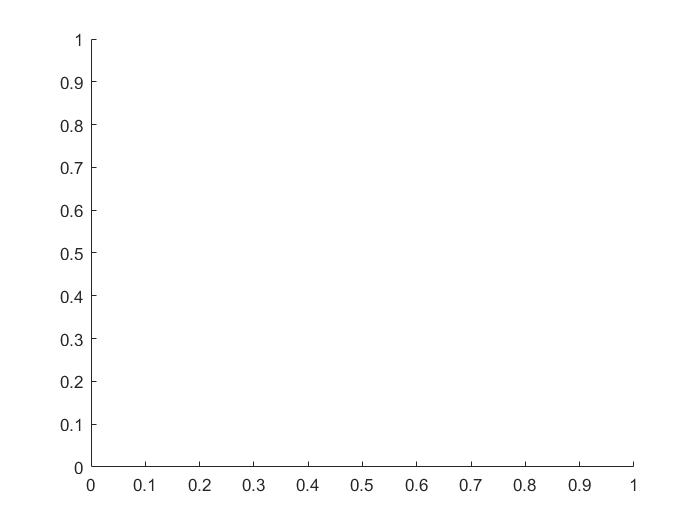

% Example solve
% ode_baseball(speed0, angle)
[T, State] = ode_baseball(40, 45);

% Visualze example
figure(); clf; hold on;

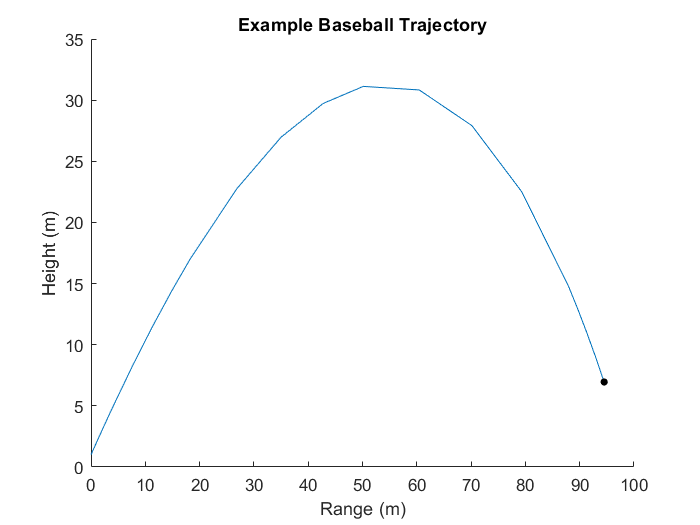


plot(State(:, 1), State(:, 2));
plot(State(end, 1), State(end, 2), ...
    "k.", "MarkerSize", 15)

xlabel("Range (m)")
ylabel("Height (m)")
title("Example Baseball Trajectory")

**Important Note**

I've designed this function to **end** the simulation once the x-position of the baseball reaches the range of the Green Monster wall. This allows me to easily extract the height of the ball at the range of the Green Monster by taking the tail `end` of the State. If I did not do this, I would need to add more data processing steps to extract this important value.

The advantage of this parameterized function is that I can sweep initial conditions to produce an ensemble of different trajectories. To answer the optimization question above, we'll need to identify the `speed0` and `angle` that correspond to a minimum `speed0` way to hit a home run.

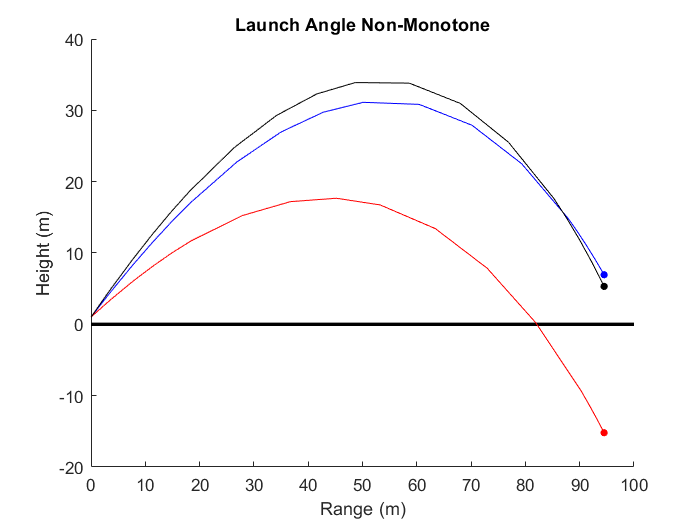

% Ensemble of trajectories
[~, State_lo] = ode_baseball(35, 35);
[~, State_hi] = ode_baseball(40, 48);

% Visualze ensemble of trajectories
figure(); clf; hold on;

plot([0, 100], [0, 0], "k-", "LineWidth", 2)
plot(State(:, 1), State(:, 2), "b");
plot(State(end, 1), State(end, 2), ...
    "b.", "MarkerSize", 15)
plot(State_lo(:, 1), State_lo(:, 2), "r");
plot(State_lo(end, 1), State_lo(end, 2), ...
    "r.", "MarkerSize", 15)
plot(State_hi(:, 1), State_hi(:, 2), "k");
plot(State_hi(end, 1), State_hi(end, 2), ...
    "k.", "MarkerSize", 15)

xlabel("Range (m)")
ylabel("Height (m)")
title("Launch Angle Non-Monotone")

**Questions**: What do you notice about these trajectories? What affect does increasing the initial angle have on the at-range height of the baseball? Does every initial angle result in a *physically meaningful* trajectory?

## Metric

Our metric will be the difference in at-range height of the baseball (see **Important Note** above) and the height of the Green Monster.

**When this metric is greater than zero, we know a home run has been hit!** This will allow us to leverage mathematical tools to make sense of, and ultimately solve, the modeling question we posed above.

% NOTE: This function defined at end of script
% function error = error_height(speed0, angle)
%     % Compute the error associated with baseball final height
%     wall_height = 11; % Green Monster height (m)
%     [~, State] = ode_baseball(speed0, angle);
%     error = State(end, 2) - wall_height; % error (m)
% end

With this metric we can run *parameter sweeps* to get a sense of how the initial speed and angle affect the end of the baseball trajectory.

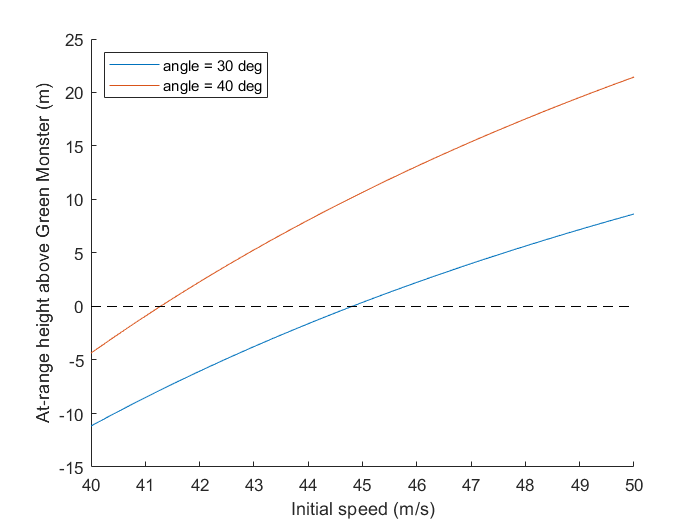

% Do speed parameter sweep
n = 25;
Speeds = linspace(40, 50, n);
angle_lo = 30;
angle_hi = 40;
Errors_lo = zeros(n, 1);
Errors_hi = zeros(n, 1);

for i = 1 : n
    Errors_lo(i) = error_height(Speeds(i), angle_lo);
    Errors_hi(i) = error_height(Speeds(i), angle_hi);
end

figure(); clf; hold on;

plot(Speeds, Errors_lo); label1 = "angle = 30 deg";
plot(Speeds, Errors_hi); label2 = "angle = 40 deg";
plot([Speeds(1), Speeds(end)], [0, 0], "k--")

xlabel("Initial speed (m/s)");
ylabel("At-range height above Green Monster (m)")
legend({label1, label2}, "Location", "NW")

**Warning**: These are not trajectories! These are abstract curves visualizing a metric against a parameter.

Since these curves are *monotone increasing*, solving for the zero-error point will give us the *minimum speed* associated with any initial angle.

## Root-finding

We could eyeball the zero-error initial speed, but Matlab provides routines for *automatically* finding the root (zero-crossing) of a function. The following function takes an angle and runs `fzero` to do this root-finding automatically.

% NOTE: This function is defined below
% function speed0 = find_speed0(angle)
%     % Find zero-error speed0 for given angle
%     speed0 = fzero(@(s) error_height(s, angle), 40);
% end

Let's apply the function and verify that it finds the roots we'd expect:

speed0_root_lo = find_speed0(angle_lo)

speed0_root_lo = 44.8007

speed0_root_hi = find_speed0(angle_hi)

speed0_root_hi = 41.2731

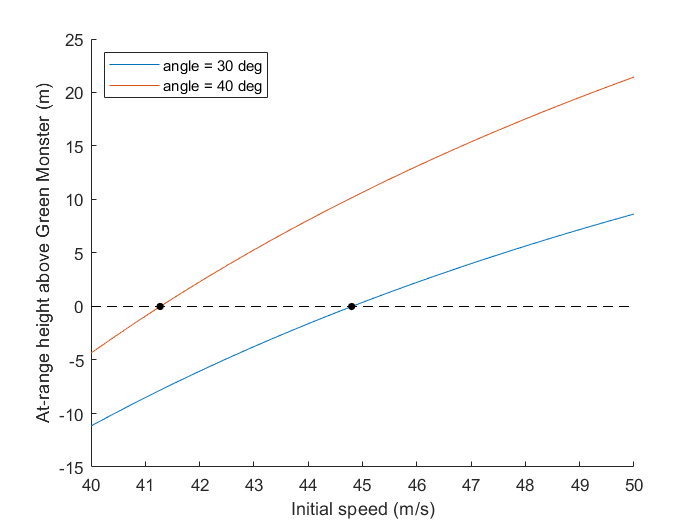


% Visualize the roots in context
figure(); clf; hold on;

plot(Speeds, Errors_lo); label1 = "angle = 30 deg";
plot(Speeds, Errors_hi); label2 = "angle = 40 deg";
plot([Speeds(1), Speeds(end)], [0, 0], "k--");
plot(speed0_root_lo, 0, "k.", "MarkerSize", 15);
plot(speed0_root_hi, 0, "k.", "MarkerSize", 15);

xlabel("Initial speed (m/s)");
ylabel("At-range height above Green Monster (m)")
legend({label1, label2}, "Location", "NW")

Yes! This gives us the lowest initial speed associated with the angle we provide.

The power of this approach is that we can now run our speed-solver for a range of angles; this gives us a view of the speeds needed to hit a home run:

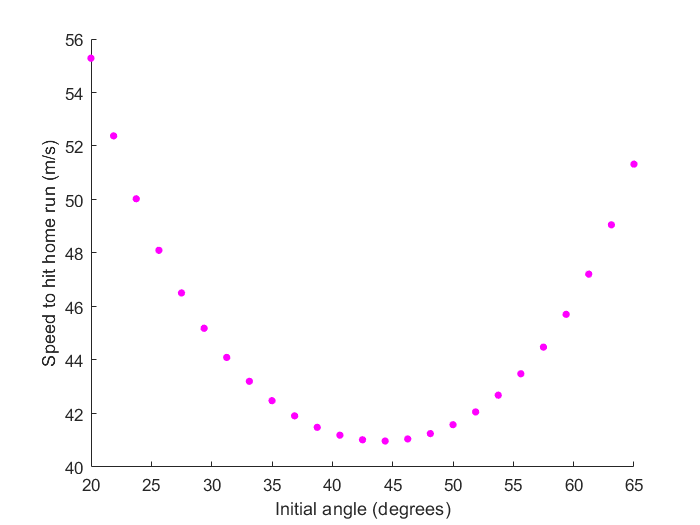

% Do angle parameter sweep of solved speed
n = 25;
Angles = linspace(20, 65, n);
Speeds_solved = zeros(n, 1);

for i = 1 : n
    Speeds_solved(i) = find_speed0(Angles(i));
end

% Visualze sweep
figure(); clf; hold on;

plot(Angles, Speeds_solved, "m.", "MarkerSize", 15)

xlabel("Initial angle (degrees)")
ylabel("Speed to hit home run (m/s)")

From this plot, we can see that there appears to be some optimal angle (around 45 degrees) that allows us to hit a minimum-speed home run.

## Minimization

Once again, we could eyeball the minimum speed, but Matlab provides a function to help find the minimum of a function. Let's run `fminsearch` to identify the angle associated with the minimum speed.

% Find the minimum speed
angle_opt = fminsearch(@find_speed0, 45)

angle_opt = 44.1569

Once we have the optimal angle, we can run it back through our `find_speed()` function to compute the minimum speed.

% Compute speed associated with optimized angle
speed0_opt = find_speed0(angle_opt)

speed0_opt = 40.9707

And we can visualize this minimum value in the context of our plot:

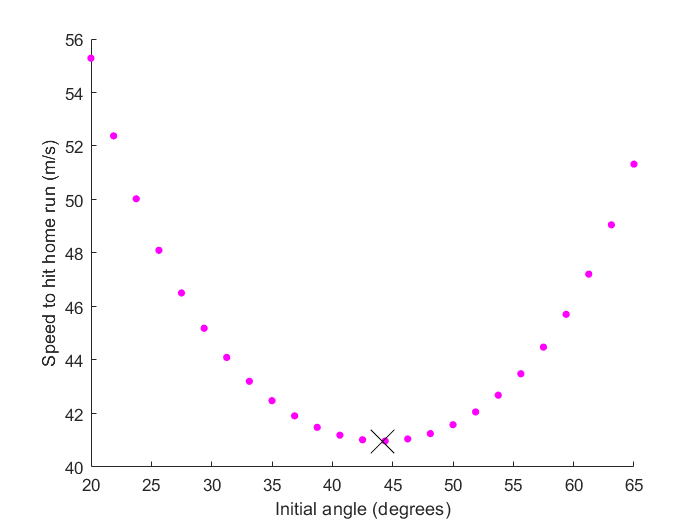

% Visualze minimum in context
figure(6); clf; hold on;

plot(Angles, Speeds_solved, "m.", "MarkerSize", 15)
plot(angle_opt, speed0_opt, "kx", "MarkerSize", 20)

xlabel("Initial angle (degrees)")
ylabel("Speed to hit home run (m/s)")

Finally, we should verify this minimum in our original model; let's make sure our optimized values actually correspond to a home run:

% Verify the minimum
[T_opt, State_opt] = ode_baseball(speed0_opt, angle_opt);
x_opt = State_opt(end, 1)

x_opt = 94.5000

y_opt = State_opt(end, 2)

y_opt = 11.0000

Remember that the Green Monster is 94.5 meters away from home and is 11 meters tall: We have indeed found the solution!

## Helper Functions

function error = error_height(speed0, angle)
    % Compute the error associated with baseball final height
    wall_height = 11; % Green Monster height (m)
    [~, State] = ode_baseball(speed0, angle);
    
    % Since ode_baseball ends at x == wall_range, 
    % we can simply extract the end height
    error = State(end, 2) - wall_height; % error (m)
end

function speed0 = find_speed0(angle)
    % Find zero-error speed0 for given angle
    speed0 = fzero(@(s) error_height(s, angle), 40);
end